## Import

 
% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "Time_s_", "IntensityCh1"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

[file, folder] = uigetfile('*.txt');
fullfile(folder, file)

ans = 'U:\Projekte an Analysis1\Christian\Misc\Hannah\vCMC_Cdh5Cre_Tam-_ transients_04.txt'

% Import the data
tbl = readtable(fullfile(folder, file), opts);

% Clear temporary variables
clear opts

% Display results
tbl

tbl = 60001×3 table
    Time     Time_s_     IntensityCh1
    ____    _________    ____________

      1             0       28.268   
      2     0.0009216       24.623   
      3     0.0018432       23.061   
      4     0.0027648       23.375   
      5     0.0036864       24.916   
      6      0.004608       24.428   
      7     0.0055296       25.072   
      8     0.0064512       24.865   
      9     0.0073728       25.254   
     10     0.0082944       25.697   
     11      0.009216       24.111   
     12      0.010138       25.996   
     13      0.011059       24.855   
     14      0.011981       25.645   
     15      0.012902       24.934   
     16      0.013824       23.113   


## Cleanup and Prep.

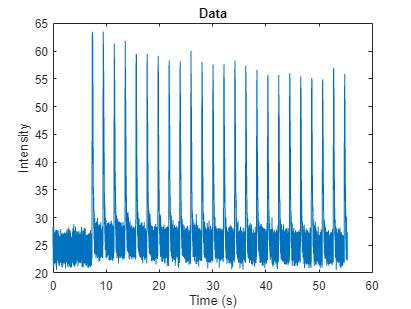

 
tbl=tbl(~any(ismissing(tbl),2),:);
tbl = tbl(:,2:3);
tbl.Properties.VariableNames = {'Time', 'Intensity'};
plot(tbl.Time, tbl.Intensity)
title("Data")
xlabel("Time (s)")
ylabel("Intensity")

## Smooth

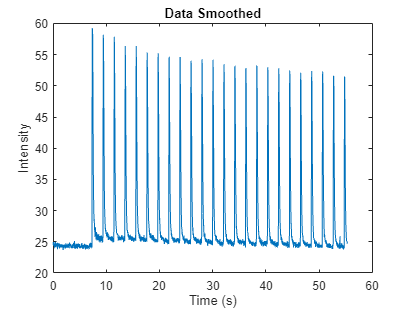

 
tbl = smoothdata(tbl,"movmedian",50,"DataVariables","Intensity");
plot(tbl.Time, tbl.Intensity)
title("Data Smoothed")
xlabel("Time (s)")
ylabel("Intensity")

Time = tbl.Time;
Intensity = tbl.Intensity;

## Find Peaks

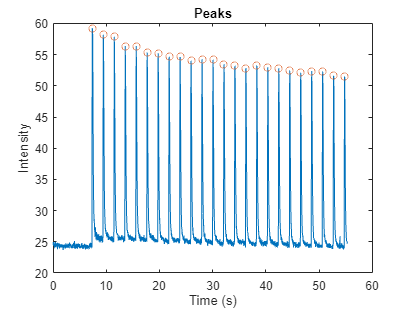

 
MinPeakProminence = 10;
MinPeakDistance = 1;
[pks,timePeak] = findpeaks(Intensity, Time ,'MinPeakProminence',MinPeakProminence,'MinPeakDistance', MinPeakDistance); %Prominence: https://de.mathworks.com/help/signal/ug/prominence.html
peakInterval = diff(timePeak);
plot(Time,Intensity, timePeak,pks,'o')
xlabel('Time (s)')
ylabel('Intensity')
title("Peaks")

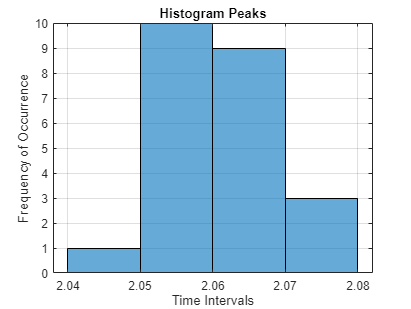

histogram(peakInterval)
title("Histogram Peaks")
grid on
xlabel('Time Intervals (s)')
ylabel('Frequency of Occurrence')

AverageDistance_Peaks = mean(diff(timePeak))

AverageDistance_Peaks = 2.0614

## Fit

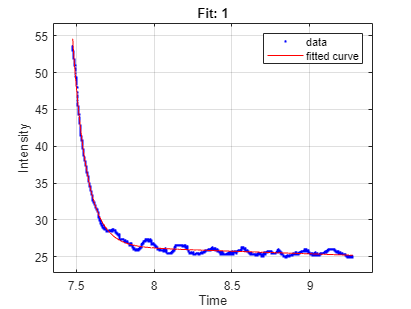

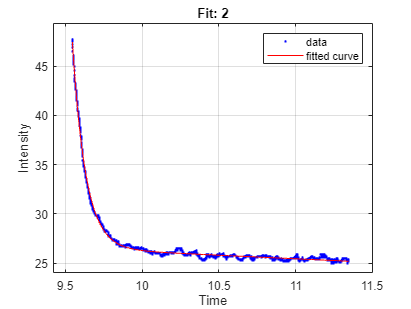

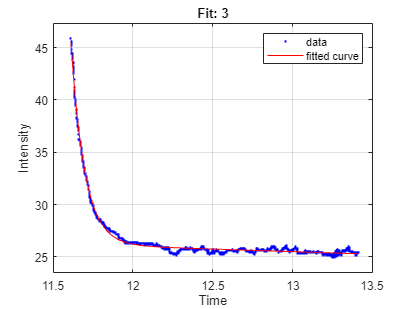

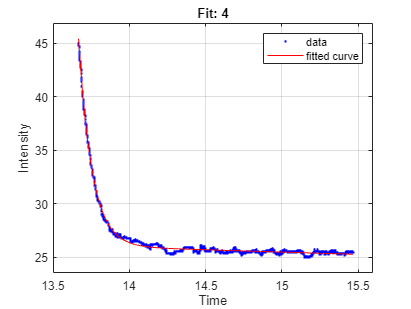

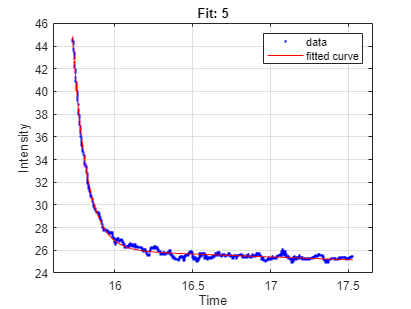

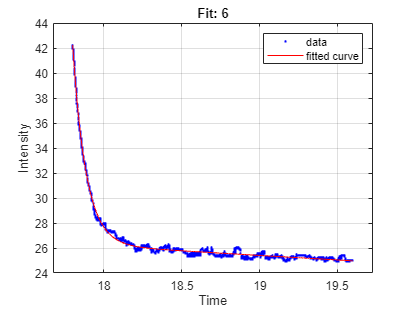

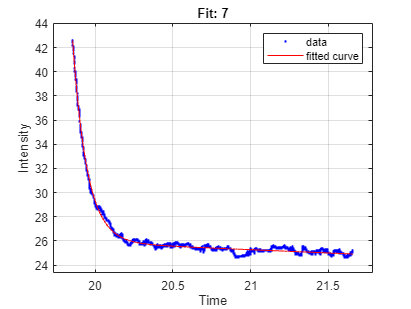

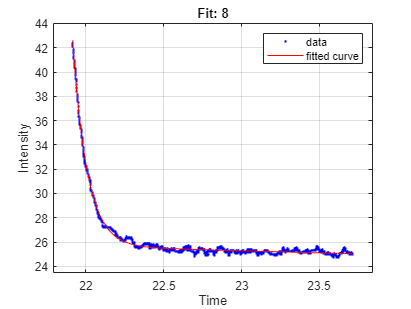

 
fitDistance = 1.9;
for i = 1: numel(timePeak)
     [~, ix1] = min(abs(Time - (timePeak(i)+0.1)));
     [~, ix2] = min(abs(Time - (timePeak(i)+fitDistance)));
    TimeFit = Time(ix1:ix2);
    IntensityFit = Intensity(ix1:ix2);
    [fitresult, gof] = createFit(TimeFit, IntensityFit);
    title(append("Fit: ", num2str(i)));
    axis padded
    tauFast = log(1/2) / fitresult.b;
    tauSlow = log(1/2) / fitresult.d;
    gof.tauSlow = tauSlow;
    gof.tauFast = tauFast;
    fitData(i) = struct('fit', fitresult, 'fitInfo', gof, 'Intensity', IntensityFit, 'Time', TimeFit);
end

## Taus

 
"T1/2 Slow"

ans = "T1/2 Slow"

for i = 1: numel(timePeak)
    slowTaus(i) = fitData(i).fitInfo.tauSlow;
    slowTaus(i)
end

ans = 47.8854

ans = 47.1363

ans = 68.3980

ans = 78.7992

ans = 67.7701

ans = 46.4094

ans = 61.5444

ans = 96.5863

ans = 72.7552

ans = 79.9265

ans = 79.2983

ans = 46.6925

ans = 76.7361

ans = 96.6849

ans = 66.3473

ans = 89.8841

ans = 73.2330

ans = 66.2035

ans = 110.2818

ans = 82.0539

ans = 63.7116

ans = 53.3631

ans = 87.6641

ans = 115.6644

"T1/2 Fast"

ans = "T1/2 Fast"


for i = 1: numel(timePeak)
    fastTaus(i) = fitData(i).fitInfo.tauFast;
    fastTaus(i)
end

ans = 0.1195

ans = 0.1152

ans = 0.1148

ans = 0.1177

ans = 0.1199

ans = 0.1141

ans = 0.1232

ans = 0.1249

ans = 0.1231

ans = 0.1188

ans = 0.1218

ans = 0.1155

ans = 0.1181

ans = 0.1225

ans = 0.1216

ans = 0.1231

ans = 0.1243

ans = 0.1158

ans = 0.1296

ans = 0.1185

ans = 0.1209

ans = 0.1201

ans = 0.1194

ans = 0.4456

append("Median Tau1/2 Slow: ", num2str(median(slowTaus)), " +- ", num2str(std(slowTaus)))

ans = "Median Tau1/2 Slow: 72.9941 +- 19.183"

append("Median Tau1/2 Fast: ", num2str(median(fastTaus)), " +- ", num2str(std(fastTaus)))

ans = "Median Tau1/2 Fast: 0.11999 +- 0.066553"

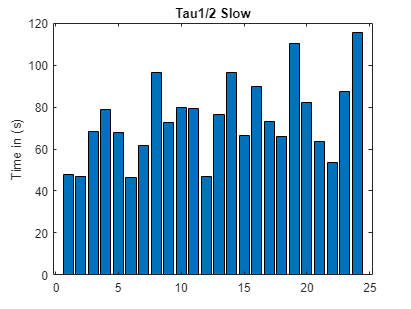


figure;bar(slowTaus)
title("Tau1/2 Slow")
ylabel("Time in (s)")

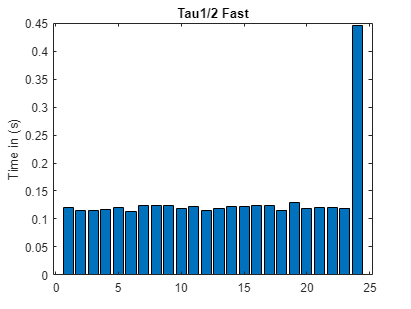

figure;bar(fastTaus)
title("Tau1/2 Fast")
ylabel("Time in (s)")

## Time To

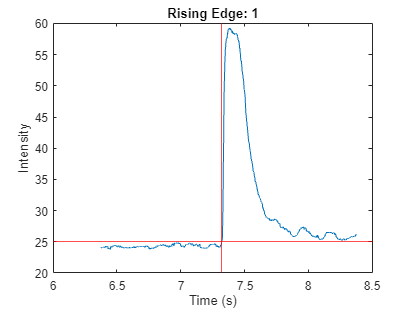

ans = "Time to Peak: 0.053453"

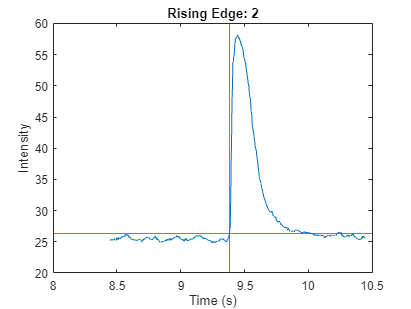

ans = "Time to Peak: 0.065434"

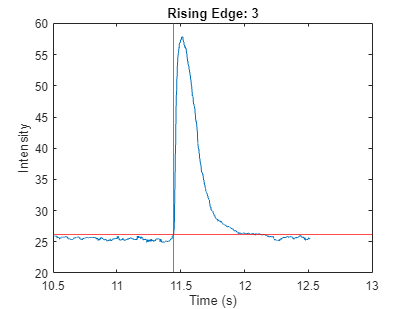

ans = "Time to Peak: 0.06912"

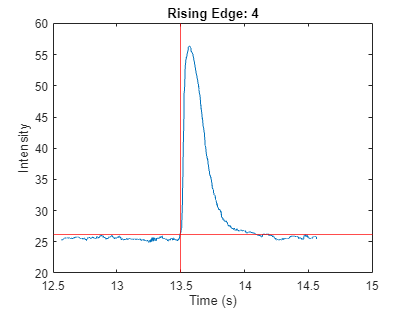

ans = "Time to Peak: 0.072806"

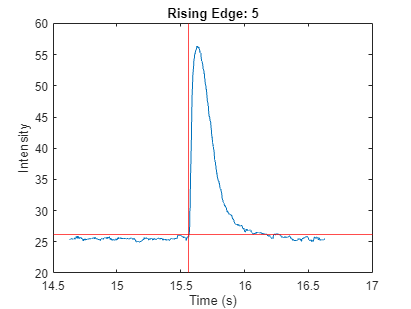

ans = "Time to Peak: 0.06359"

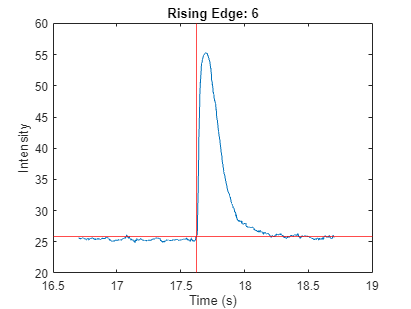

ans = "Time to Peak: 0.076493"

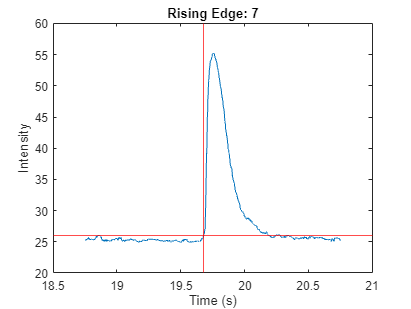

ans = "Time to Peak: 0.076493"

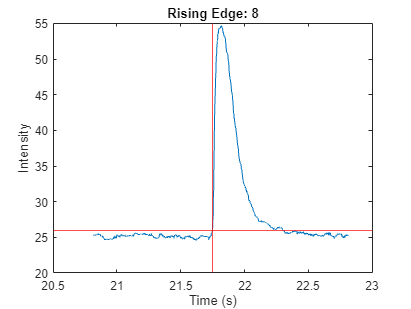

ans = "Time to Peak: 0.067277"

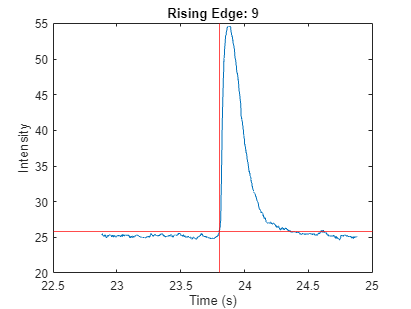

ans = "Time to Peak: 0.080179"

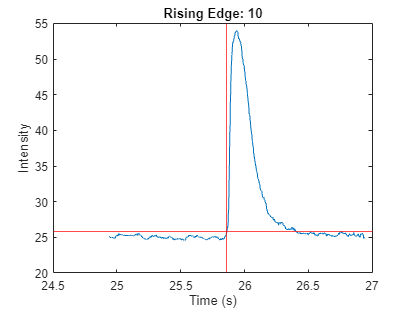

ans = "Time to Peak: 0.077414"

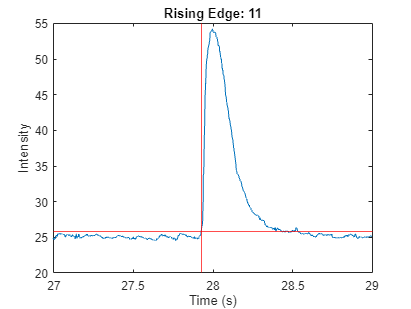

ans = "Time to Peak: 0.070042"

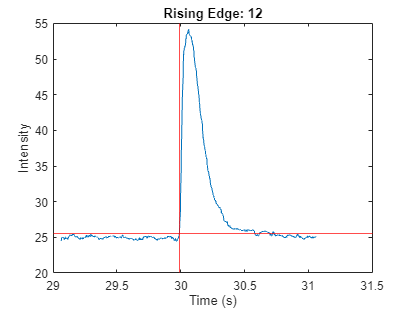

ans = "Time to Peak: 0.072806"

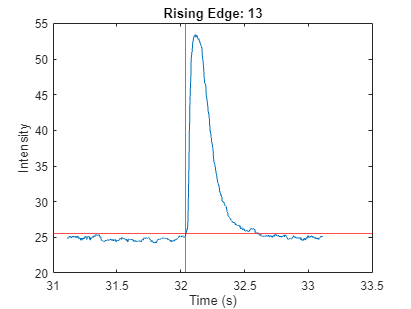

ans = "Time to Peak: 0.071885"

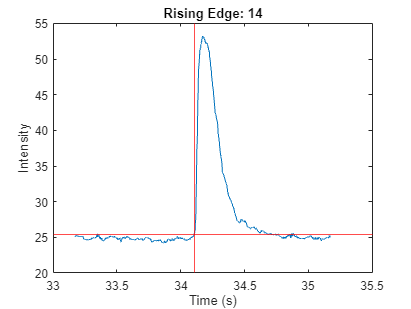

ans = "Time to Peak: 0.064512"

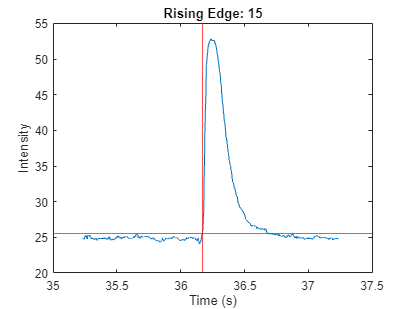

ans = "Time to Peak: 0.066355"

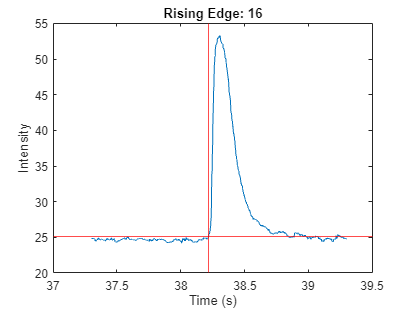

ans = "Time to Peak: 0.082944"

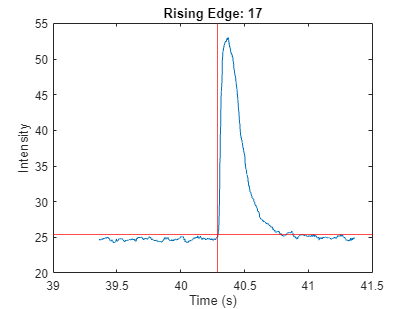

ans = "Time to Peak: 0.070963"

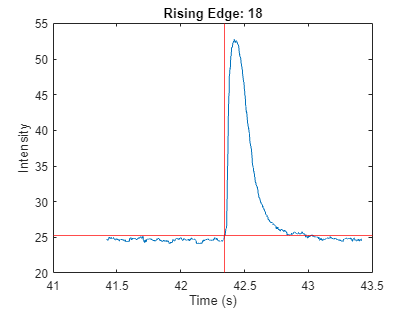

ans = "Time to Peak: 0.077414"

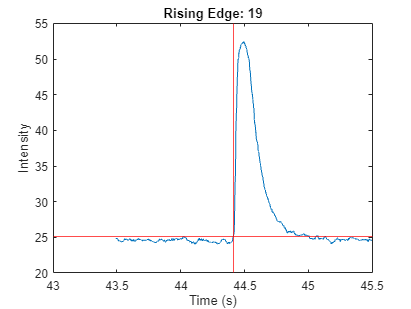

ans = "Time to Peak: 0.080179"

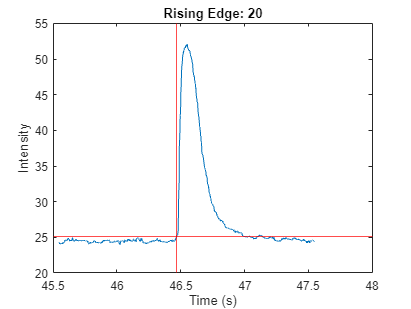

ans = "Time to Peak: 0.080179"

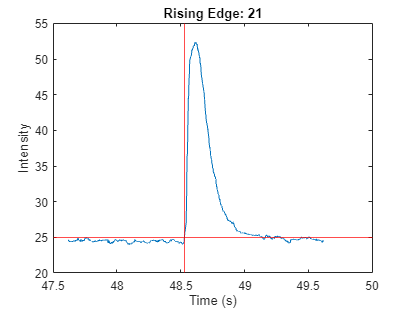

ans = "Time to Peak: 0.088474"

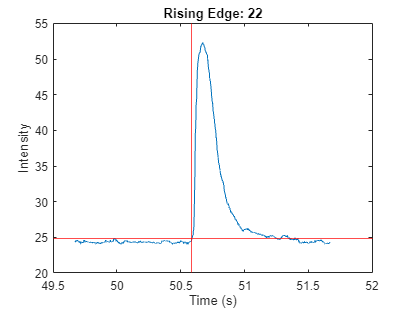

ans = "Time to Peak: 0.085709"

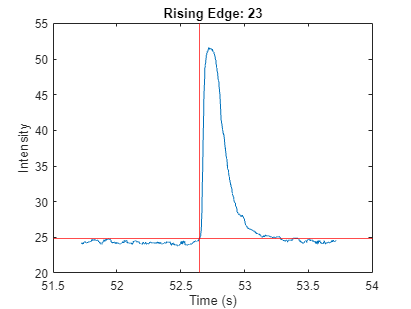

ans = "Time to Peak: 0.073728"

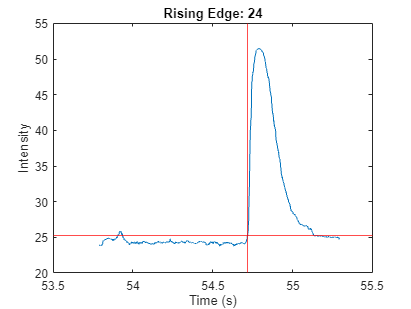

ans = "Time to Peak: 0.06912"

 
for i = 1: numel(timePeak)
    [~, ix3] = min(abs(Time - (timePeak(i)-1)));
    [~, ix4] = min(abs(Time - (timePeak(i)+1)));
    TimeTimeToCalc = Time(ix3:ix4);
    IntensityTimeToCalc = Intensity(ix3:ix4);
    ipt = findchangepts(IntensityTimeToCalc,'Statistic',"std");
    figure;
    plot(TimeTimeToCalc, IntensityTimeToCalc);
    title(append("Rising Edge: ", num2str(i)));
    xlabel("Time (s)")
    ylabel("Intensity")
    axis padded
    xline(TimeTimeToCalc(ipt), 'Color', 'red');
    yline(IntensityTimeToCalc(ipt), 'Color', 'red');
    timeStart = TimeTimeToCalc(ipt);

    timePeakStart(i,:) = [ipt timeStart];
    append("Time to Peak: ", num2str(timePeak(i)-timeStart))
end

"Time to Peak (ms):"

ans = "Time to Peak (ms):"

for i = 1: numel(timePeak)
 TimeToPeak(i) = (timePeak(i)-timePeakStart(i,2)) * 1000;
end
 TimeToPeak'

ans =    53.4528
   65.4336
   69.1200
   72.8064
   63.5904
   76.4928
   76.4928
   67.2768
   80.1792
   77.4144


append("Median Time to peak: ", num2str(median(TimeToPeak)), " +- ", num2str(std(TimeToPeak)))

ans = "Median Time to peak: 72.8064 +- 7.9089"

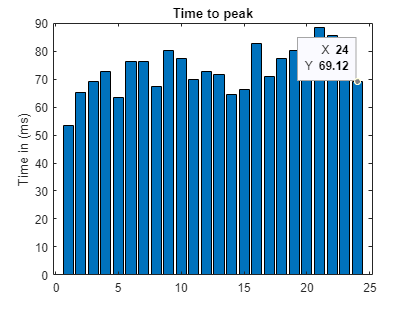


figure;bar(TimeToPeak)
title("Time to peak")
ylabel("Time in (ms)") 

## Data

 
dataTable = table(fastTaus', slowTaus', pks, timePeak, timePeakStart(:,2), TimeToPeak');
dataTable.Properties.VariableNames ={'FastTau1/2 (s)', 'SlowTau1/2 (s)', 'Peak Intensity', 'Peak Time (s)', 'Rising Edge Peak Time (s)', 'Time to Peak (ms)'};
dataTable

dataTable = 24×6 table
    FastTau1/2 (s)    SlowTau1/2 (s)    Peak Intensity    Peak Time (s)    Rising Edge Peak Time (s)    Time to Peak (ms)
    ______________    ______________    ______________    _____________    _________________________    _________________

       0.11954            47.885            59.242           7.3756                 7.3221                   53.453      
       0.11519            47.136            58.179           9.4455                   9.38                   65.434      
       0.11477            68.398            57.864           11.512                 11.443                    69.12      
       0.11774            78.799            56.381           13.567                 13.494                   72.806      
       0.11986             67.77        

## Save .Mat

 
uisave

## Save .csv

 
[folder, file] = uiputfile('*.csv')
writetable(dataTable, fullfile(file,folder))


## Save .html

 
[p,f,e]=fileparts(file);
export("AnalyseSparks.mlx",append(f, '.html'),Format="html", OpenExportedFile=true, HideCode=true)

ans = 'U:\Projekte an Analysis1\Christian\Matlab for everybody\Calcium Sparks\vCMC_Cdh5Cre_Tam-_ transients_04.html'